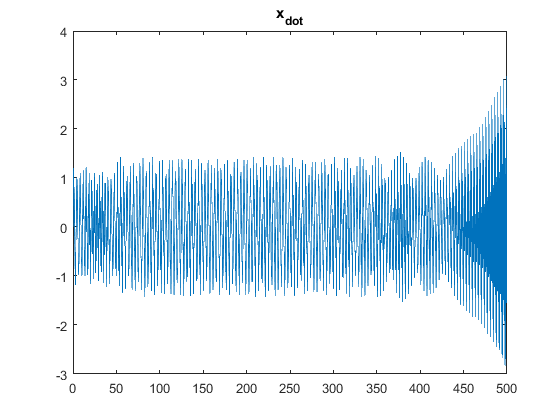

clc;
clear all;

t0 = 0;
tk = 500;
ts = [t0, tk];

y0 = [0;0;0;0;0;0;0;1;0;0];



overload = 2.5;
f_main = 50; %Hz
n_sync = 1400;
w_sync = 2*pi*n_sync/60;
n_nom = n_sync * 0.99; %RPM
w_nom = 2*pi*n_nom/60; %s^-1
P_nom = 120; %W
M_nom = P_nom/w_nom;
S_nom = (n_sync-n_nom)/n_sync;
S_stall = S_nom*(overload+sqrt((overload^2)-1));
n_stall = n_sync-S_stall*n_sync;
w_stall = 2*pi*n_stall/60;
M_stall = overload*M_nom;

m_el =@(w) (2.*M_stall.*(w_sync-w_stall).*(w_sync-w))/((w_sync-w_stall).^2+(w_sync-w).^2);




[t, y] = ode45('modelv1',ts,y0);
plot(t,y(:,1));title('x_{dot}')

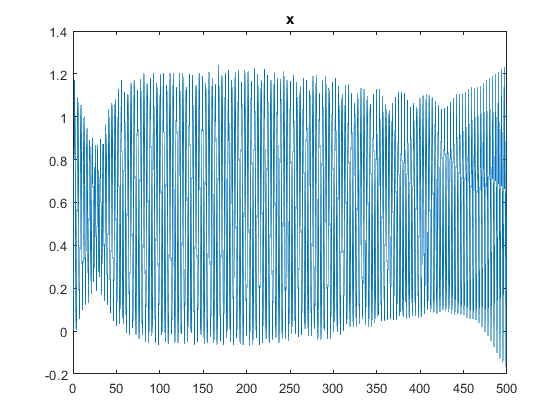

plot(t,y(:,2));title('x')

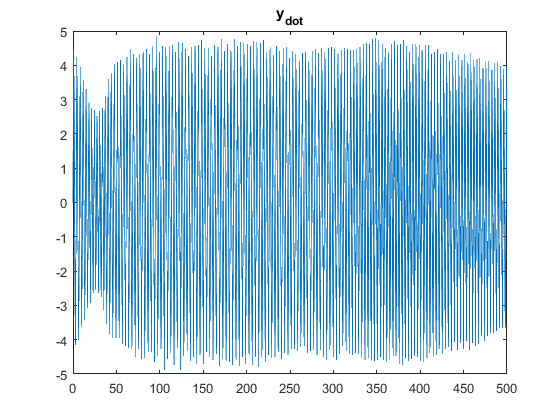

plot(t,y(:,3));title('y_{dot}')

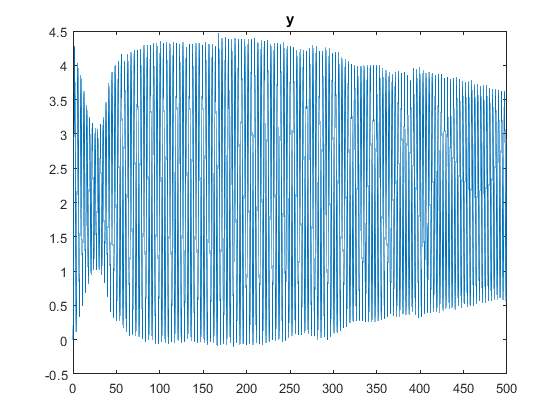

plot(t,y(:,4));title('y')

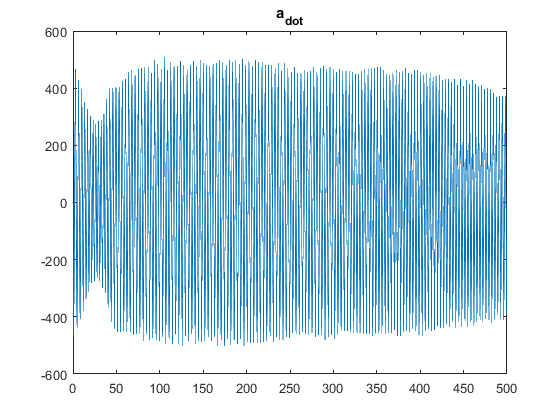

plot(t,rad2deg(y(:,5)));title('a_{dot}')

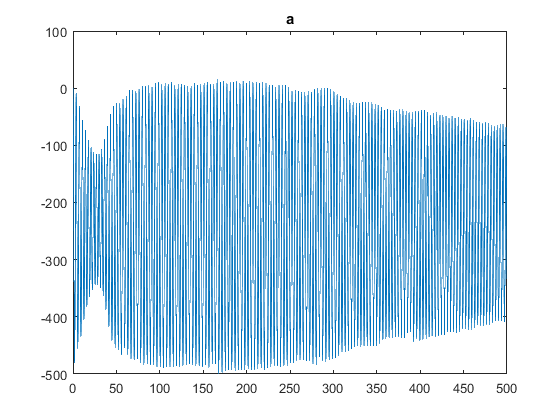

plot(t,rad2deg(y(:,6)));title('a')

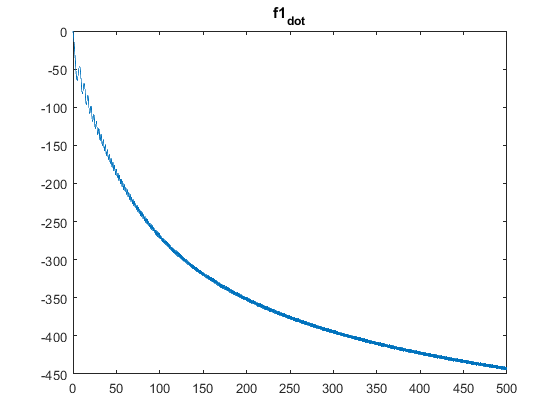

plot(t,rad2deg(y(:,7)));title('f1_{dot}')

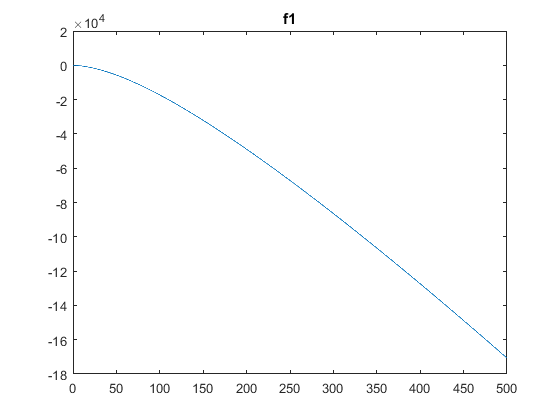

plot(t,rad2deg(y(:,8)));title('f1')

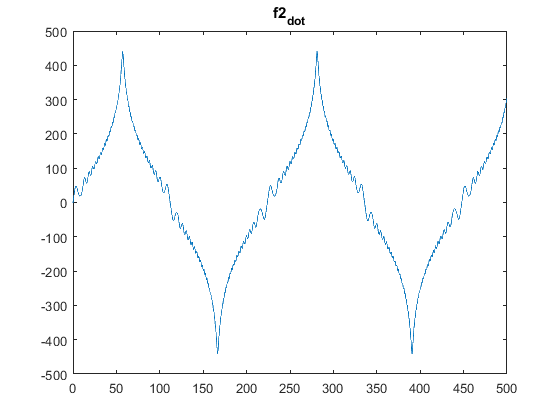

plot(t,rad2deg(y(:,9)));title('f2_{dot}')

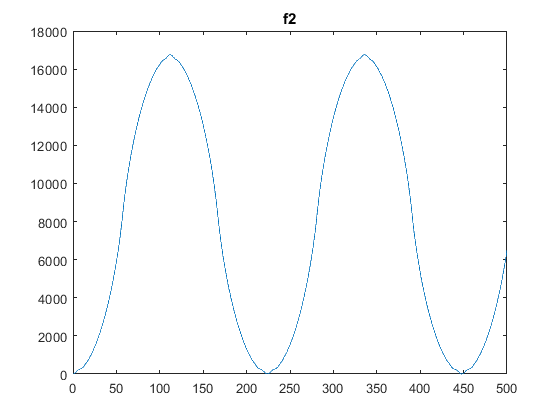

plot(t,rad2deg(y(:,10)));title('f2')